clear all

syms x
syms k

k0=1

k0 = 1

a = 1

a = 1


%B = k*(heaviside(k)-heaviside(k-k0))
B = ((2*a/pi)^(1/4)) * exp(-a*((k-k0)^2))

$$B = \frac{8045625265604515\,{\mathrm{e}}^{-{\left(k-1\right)}^{2}}}{9007199254740992}$$

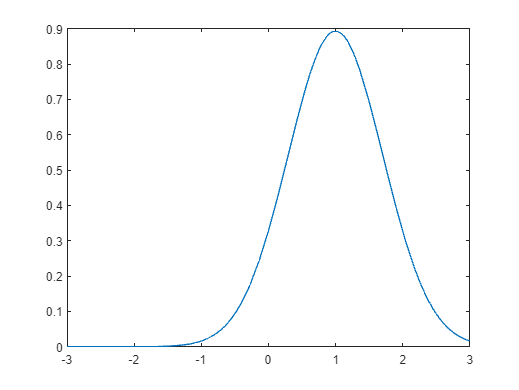


fplot(B,[-3,3])


psi=(1/sqrt(2*pi)) * int(B*exp(i*k*x),'k',-inf,inf)

$$psi = \frac{57821537106012535442281462402195\,\sqrt{\pi }\,{\mathrm{e}}^{x\,\mathrm{i}}\,{\mathrm{e}}^{-\frac{x^{2}}{4}}}{162259276829213363391578010288128}$$

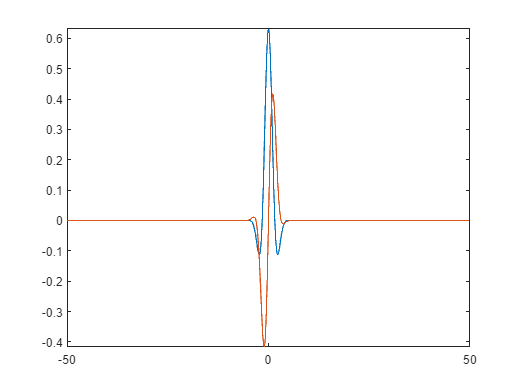


% I used this to check my Re and Im parts derived by hand were correct
%fplot(-1.0/(x*x)+cos(x)/(x*x)+sin(x)/x,[-50,50])
%hold on
%fplot(sin(x)/(x*x)-cos(x)/x)
%hold off

fplot(real(psi),[-50,50])
hold on
fplot(imag(psi),[-50,50])
hold off


%fplot(conj(psi)*psi,[-50,50])
